[**MIT License**](https://github.com/cdslaborg/paramonte#license)

[**ParaMonte: plain powerful parallel Monte Carlo library**](https://github.com/cdslaborg/paramonte)**.**

**Copyright (C) 2012-present, **[**The Computational Data Science Lab**](https://www.cdslab.org/#about)

[**https://github.com/cdslaborg/paramonte**](https://github.com/cdslaborg/paramonte)

# Making scatter plots with the ParaMonte visualization tools

**NOTE**

If you are viewing an HTML version of this MATLAB live script on the web, you can download the corresponding MATLAB live script `visualization_scatter.mlx` file to this HTML page at,

[https://github.com/cdslaborg/paramontex/tree/main/MATLAB/mlx](https://github.com/cdslaborg/paramontex/tree/main/MATLAB/mlx)

Once you download the file, open it in MATLAB to view and interact with its contents, which is the same as what you see on this page. 

First, let's clean up the MATLAB environment and make sure the path to the ParaMonte library is in MATLAB's path list.

clc;
clear all;
close all;
format compact; format long;

%%%%%%%%%%%% IMPORTANT %%%%%%%%%%%%%
% Set the path to the ParaMonte library:
% Change the following path to the ParaMonte library root directory, 
% otherwise, make sure the path to the ParaMonte library is already added
% to MATLAB's path list.

pmlibRootDir = './';
addpath(genpath(pmlibRootDir),"-begin");
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% change MATLAB's working directory to the folder containing this script
% if MATLAB Live Scripts did not create a temporary folder, we would not
% have all of these problems!

try
    setwdFilePath = websave("setwd.m","https://github.com/cdslaborg/paramontex/raw/main/MATLAB/mlx/setwd.m");
    run(setwdFilePath); % This is a MATLAB script that you can download from the same GitHub location given in the above.
catch % alas, we will have to run the simulations in MATLAB Live Script's temporary folder
    filePath = mfilename('fullpath');
    [currentDir,fileName,fileExt] = fileparts(filePath); cd(currentDir);
    cd(fileparts(mfilename('fullpath'))); % Change working directory to source code directory.
end

## ParaMonte's default visualization tools

The ParaMonte library ships with several visualization tools that automate much of the MATLAB coding required to visualize the output of the simulations performed by the ParMonte library samplers. 

By replacing the input dataFrame to these tools and following the conventions of the ParaMonte library, one can also use these visualization tools for any dataset that may not have been generated by the ParaMonte library.

Consider the following Markov chain on the web in **compact** format generated by the **ParaDRAM** sampler of the ParaMonte library to sample a MultiVariate Normal distribution. Since this is a chain file as inidicated by its suffix `"_chain.txt"` We will read this file via the ParaDRAM sampler's `readChain()` method.

pm = paramonte();
pmpd = pm.ParaDRAM();
url = "https://github.com/cdslaborg/paramontex/raw/main/MATLAB/mlx/sampling_multivariate_normal_distribution_via_paradram/out/mvn_serial_process_1_chain.txt";
pmpd.readChain(url); % read the chain file from the web


ParaDRAM - WARNING: The ParaDRAM input simulation specification `pmpd.spec.outputDelimiter` is not set.
ParaDRAM - WARNING: This information is essential for successful reading of the requested chain file(s).
ParaDRAM - WARNING: Proceeding with the default assumption of comma-delimited chain file contents...

ParaDRAM - NOTE: 1 files detected matching the pattern: 
ParaDRAM - NOTE: "https://github.com/cdslaborg/paramontex/raw/master/MATLAB/mlx/sampling_multivariate_normal_distribution_via_paradram/out/mvn_serial_process_1_chain.txt"

ParaDRAM - NOTE: processing file: "D:\Dropbox\Projects\20180101_ParaMonte\paramontex\MATLAB\mlx\visualization\temp_20201004_041647_259.txt"
ParaDRAM - NOTE: reading the file contents... 
ParaDRAM - NOTE: done in 0.784340 seconds.
ParaDRAM - NOTE: ndim = 4, count = 50000

ParaDRAM - NOTE: computing the sample correlation matrix...

ParaDRAM - NOTE: creating the heatmap plot object from scratch...
ParaDRAM - NOTE: done in 0.992940 seconds.
ParaDRAM - NOTE: 

This method automatically generates a set of tools that can be used to visualize the contents of the compact chain file. Note that these visualization tools are not unique to this particular method of the ParaDRAM sampler or other ParaMonte samplers. For the sake of illustration however, we will create plots using the above dataset read via `readChain()` method of the ParaDRAM routine.

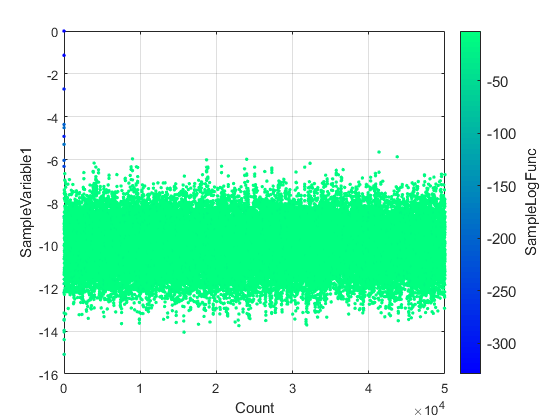

chain = pmpd.chainList{1};
chain.plot.scatter.make();

Be default, the visualization tools are loaded with a set of predefined settings. For example, scatter plots are by default colored (unless mutiple variables are to be displayed). These however, can be readily changed. For example, to change the colormap,

chain.plot.scatter.colormap.values

ans = "winter"

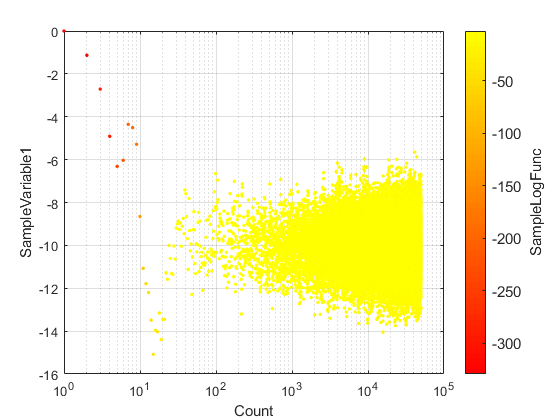

chain.plot.scatter.colormap.values = autumn;
chain.plot.scatter.axes.kws.xscale = "log";
chain.plot.scatter.make()

To draw the colored scatter, the ParaMonte visualizer utilizes the `scatter()` function of MATLAB. One can pass pairs of (key,value) properties to this MATLAB function by defining those **keyword** properties in the `scatter`` component of the scatter object, `

chain.plot.scatter.scatter.kws

ans = struct with no fields.


In addition, there scatter **positional arguments** that must be seperately passed to the scatter plot of MATLAB, these properties are separately listed one level up,

chain.plot.scatter.scatter

ans = struct with fields:
     marker: "o"
     filled: 1
      color: []
       size: 7
    enabled: 1
        kws: [1×1 struct]

If the plot is supposed to be color-mapped, do not touch the `color` property seen in the above, use the `colormap` property of the plot object instead to change the color. For example,

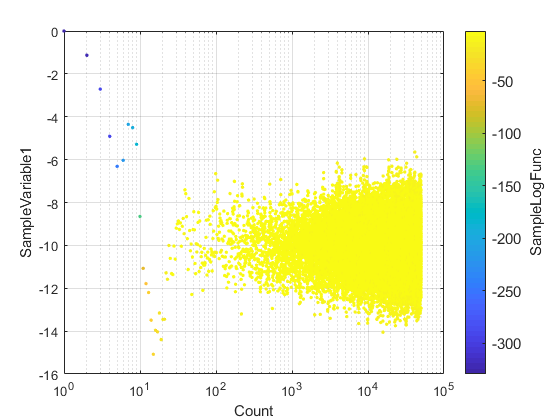

chain.plot.scatter.axes.kws.xscale = "log";
chain.plot.scatter.colormap.values = "parula";
chain.plot.scatter.make();

To **reset** the properties of the plot object to the default settings, try, 

chain.plot.scatter.reset();

ParaDRAM - NOTE: resetting the properties of the scatter plot...


To reset the entire plot object including reading the data again from the input dataFrame, try, 

chain.plot.scatter.reset("hard");

ParaDRAM - NOTE: creating the scatter plot object from scratch...


Similarly, to change the properties of the **colorbar**, try, 

chain.plot.scatter.colorbar.kws

ans = struct with fields:
    fontSize: []

chain.plot.scatter.colorbar.kws.fontSize = 15;

To change properties that do not exist, simple add them to the `kws` component, for example, 

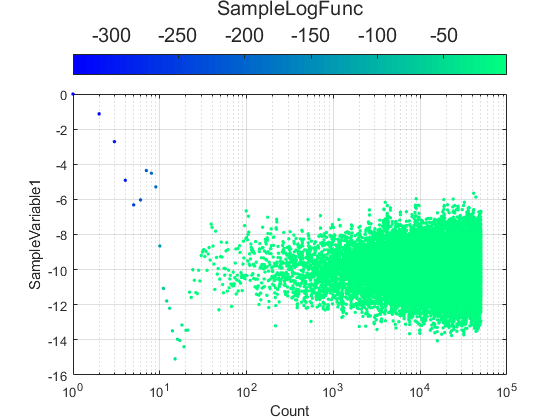

chain.plot.scatter.colorbar.kws.location = "northoutside";
chain.plot.scatter.make()
set(gca, "xscale","log")

chain.plot.scatter.colorbar.kws

ans = struct with fields:
    fontSize: 15
    location: "northoutside"

Remember that a handle to all objects in the plot is also stored in the `currentFig` component of the object. Most of the properties of the figure, axes, and the plots can be also changed directly via these handles. For example, to change the colorbar label, we could try,

chain.plot.scatter.currentFig.colorbar.Label.String

ans = 'SampleLogFunc'

chain.plot.scatter.reset();

ParaDRAM - NOTE: resetting the properties of the scatter plot...


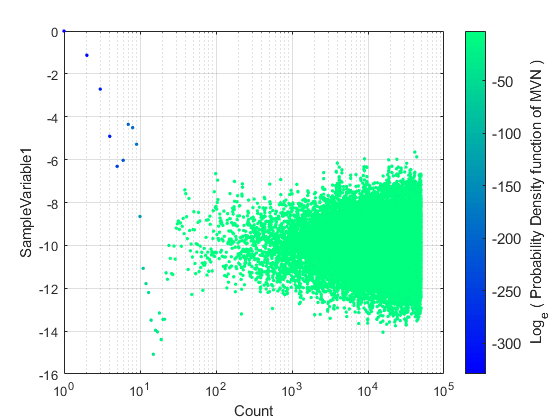

chain.plot.scatter.axes.kws.xscale = "log";
chain.plot.scatter.make()
chain.plot.scatter.currentFig.colorbar.Label.FontSize = 11;
chain.plot.scatter.currentFig.colorbar.Label.Interpreter = "tex"; % set the interpreter for the colorbar
chain.plot.scatter.currentFig.colorbar.Label.String = "Log_e ( Probability Density function of MVN )";

## Choosing a different column of data for colormap

By default, the column named `SampleLogFunc` is taken as the colormap values. 

chain.plot.scatter.ccolumns

ans = "SampleLogFunc"

This can eb easily changed o any other column in data via the attribute `ccolumns` (standing for **c**olor-**columns**),

chain.plot.scatter.reset("hard")

ParaDRAM - NOTE: creating the scatter plot object from scratch...


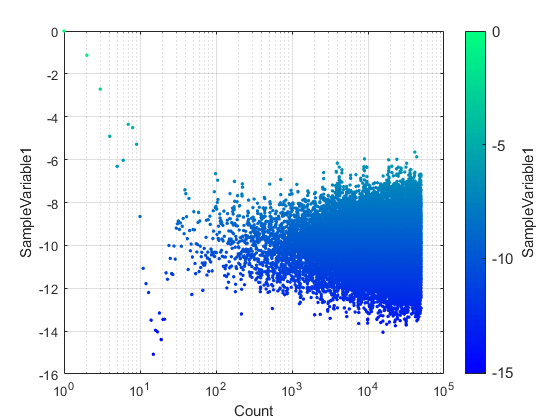


chain.plot.scatter.ccolumns = "SampleVariable1";

chain.plot.scatter.axes.kws.xscale = "log";
chain.plot.scatter.make()

## Unicolor plot

Turning the colormap off is very simple,

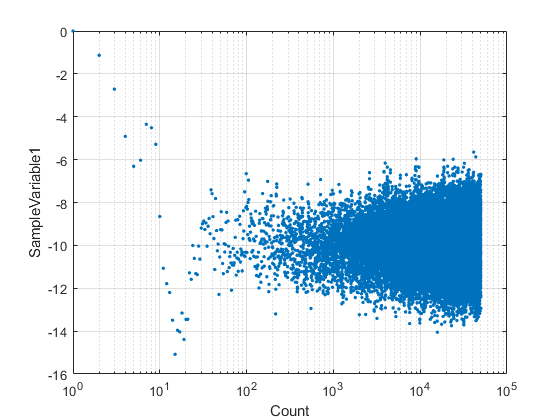

chain.plot.scatter.colormap.enabled = false; % make monocolor plot
chain.plot.scatter.axes.kws.xscale = "log";
chain.plot.scatter.make();

## Plotting multiple columns of data in a single plot

The columns of data that are plotted are determined by the corresponding column names in `xcolumns` and `ycolumns` of the plot object:

- If `xcolumns` is set to empty `[]`, then the count of data will be used as the x values,

- If y`columns` is set to empty `[]`, then the all data columns will be drawn on the same plot  (not recommended),

chain.df.Properties.VariableNames

ans = 1×11 cell array
    {'ProcessID'}    {'DelayedRejectionStage'}    {'MeanAcceptanceRate'}    {'AdaptationMeasure'}    {'BurninLocation'}    {'SampleWeight'}    {'SampleLogFunc'}    {'SampleVariable1'}    {'SampleVariable2'}    {'SampleVariable3'}    {'SampleVariable4'}

chain.plot.scatter.xcolumns

ans =
  0×0 empty cell array


chain.plot.scatter.ycolumns

ans = "SampleVariable1"

To make plots multiple columns of data in a single plot, simply add the column names to the corresponding component, or more simply,

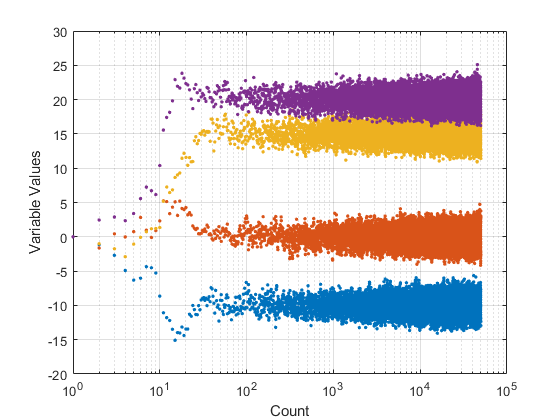

chain.plot.scatter.make("ycolumns", [8,"SampleVariable4", 9:10]) % notice the ability to mix column number with column names, or simply pass column ranges

Or make bivariate plot of variables against each other, 

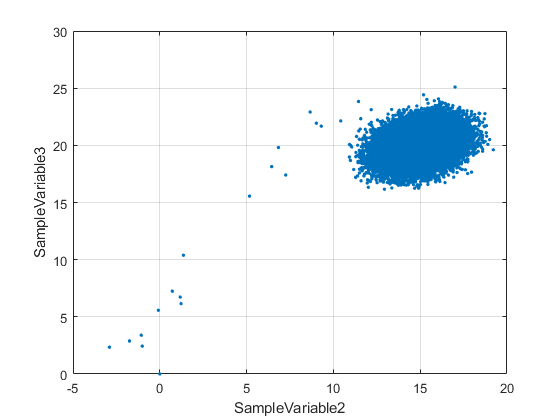

chain.plot.scatter.axes.kws.xscale = "linear";
chain.plot.scatter.make("xcolumns", "SampleVariable2", "ycolumns", 10)

or, multiple variables against a single variable,

chain.plot.scatter.reset("hard");

ParaDRAM - NOTE: creating the scatter plot object from scratch...


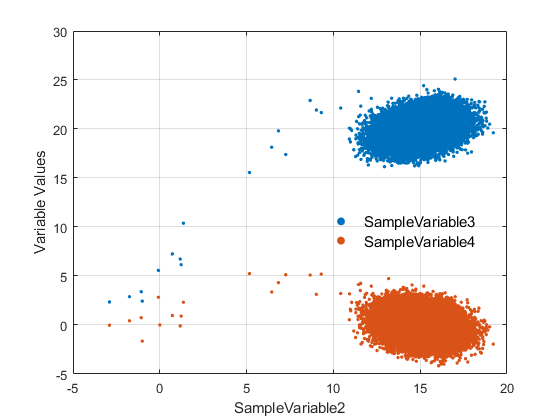

chain.plot.scatter.colormap.enabled = false;
chain.plot.scatter.legend.enabled = true;
chain.plot.scatter.make("xcolumns", "SampleVariable2", "ycolumns", [10,11])

## Plotting specific rows of data

Selected rows of data can be also plotted, if not all data observations have to be included. For example, we can exclude the burnin episode as determined by the ParaMonte sampler, 

chain.plot.scatter.reset();

ParaDRAM - NOTE: resetting the properties of the scatter plot...


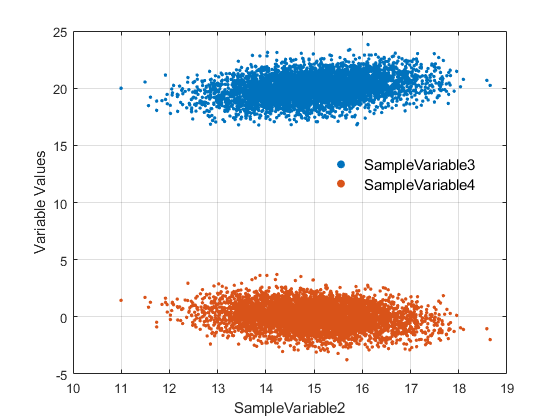

chain.plot.scatter.colormap.enabled = false;
chain.plot.scatter.legend.enabled = true;

burnin = chain.df.BurninLocation(end); % get the inferred burning location at the end of the chain

chain.plot.scatter.rows = burnin:10:chain.count; % plot every one out of 10 data rows, starting from the burnin location to the end of the chain.
chain.plot.scatter.make("xcolumns", "SampleVariable2", "ycolumns", [10,11]);

or we could plot a logarithmically-spaced selection of rows of the dataFrame, 

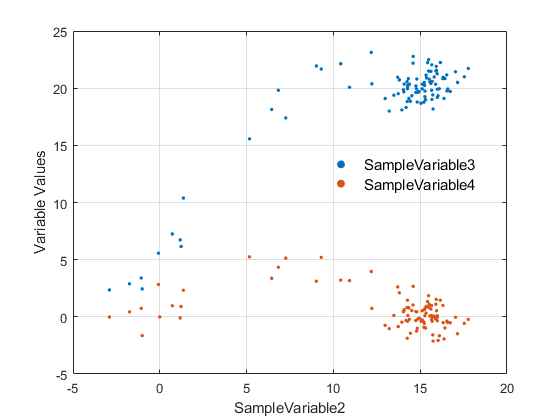

chain.plot.scatter.rows = chain.plot.scatter.getLogLinSpace( 1.1 ... base of the logarithm
                                                           , 1.0 ... the skip size 
                                                           ... , 1 ... lower limit of the generated range (optional, default is one)
                                                           ... , 1 ... upper limit of the generated range (optional, default is the total number of rows)
                                                           );
chain.plot.scatter.make();

## Adding targets to the plot

One can also **add target values** to the plots, use the `target()` component of the plot object. For example, to add the location of the burnin of the chain to the plot, one could try, 

chain.plot.scatter.reset("hard");

ParaDRAM - NOTE: creating the scatter plot object from scratch...


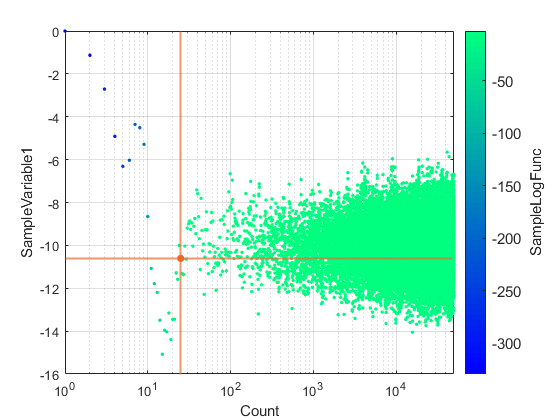

chain.plot.scatter.make()
burnin = chain.df.BurninLocation(end); % get the inferred burning location at the end of the chain
chain.plot.scatter.target.values = [ burnin, chain.df.SampleVariable1(burnin) ];
chain.plot.scatter.target.make();
set(gca,"xscale","log");

If we are interested only in the scatter point and not the lines, we can disable those lines via (in addition to changing the size, color, and marker of the scatter point),

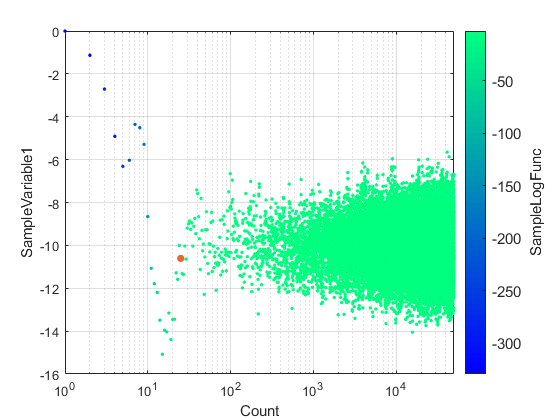

chain.plot.scatter.make()
chain.plot.scatter.target.vline.enabled = false; % disable vertical line
chain.plot.scatter.target.hline.enabled = false; % disable horizontal line
chain.plot.scatter.target.make();
set(gca,"xscale","log");

To change the size, style, and color of the scatter point, we can try,

chain.plot.scatter.target.scatter

ans = struct with fields:
    enabled: 1
        kws: [1×1 struct]
      color: [0.910000000000000 0.410000000000000 0.170000000000000]
     filled: 1
     marker: "o"
       size: 30

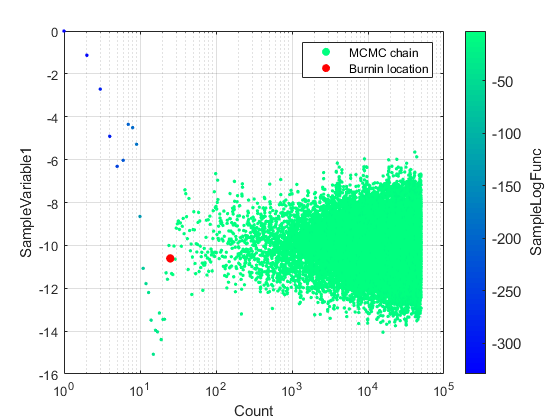

chain.plot.scatter.target.scatter.size = 40; % this is not a keyword attribute of the scatter() plot of MATLAB and therefore, not in kws component
chain.plot.scatter.target.scatter.color = "red"; % this is not a keyword attribute of the scatter() plot of MATLAB and therefore, not in kws component
chain.plot.scatter.target.scatter.marker = "O"; % set the marker attribute
chain.plot.scatter.axes.kws.xscale = "log";
chain.plot.scatter.make()
chain.plot.scatter.target.vline.enabled = false;
chain.plot.scatter.target.hline.enabled = false;
chain.plot.scatter.target.make( "values", [ burnin, chain.df.SampleVariable1(burnin) ] );
legend("MCMC chain","Burnin location")

More interestingly, one may want to add a horizontal line as the target, representing for example the **mean** and the **standard deviation** of the sample, 

chain.plot.scatter.reset();

ParaDRAM - NOTE: resetting the properties of the scatter plot...


chain.plot.scatter.axes.kws.xscale = "log";
data.avg = mean(chain.df.SampleVariable1(burnin:end));
data.std = std(chain.df.SampleVariable1(burnin:end));

chain.plot.scatter.make();

chain.plot.scatter.target.hline.kws.linewidth = 1.5;
chain.plot.scatter.target.make ( "values"  , [ nan, data.avg ] ); % horizontal line representing the mean of data

chain.plot.scatter.target.hline.kws.linestyle = ":";
chain.plot.scatter.target.make ( "values"  , [ nan, data.avg + data.std ... % horizontal line representing the 1-sigma upper limit of data
                                          ; nan, data.avg - data.std ... % horizontal line representing the 1-sigma lower limit of data
                                          ] ...
                            );

In the above example, each **row** of the input `values` represents **a separate target** to be added to the plot. **By convension, if any component of the input values is **`nan`**, that target corresponding to that component will not be added to the plot.** For example,

chain.plot.scatter.target.make ( "values"  , [ nan, data.avg ] );

is equivalent to,

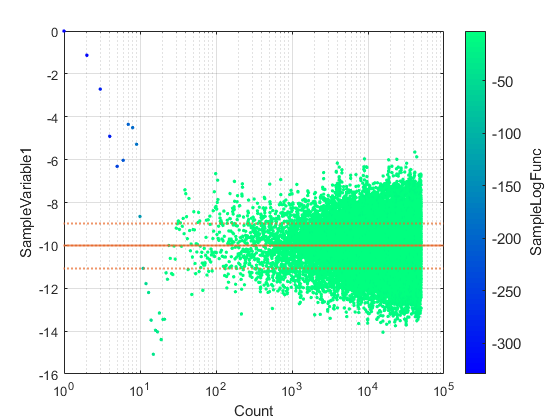

chain.plot.scatter.target.vline.enabled = false;
chain.plot.scatter.target.scatter.enabled = false;
chain.plot.scatter.target.make ( "values"  , [ 0, data.avg ] ); % or any value other than zero, which will be ignored anyway.

## Exporting figures to external files

To extract a figure to an external PNG file, try,

chain.plot.scatter.exportFig("exportedFigure.png","-m4")

The above command will extract the current active figure to an output file with the relatively high resoluton as specified by the flag `-m4`. To make the exported figure smaller, one could specify `-m2` instead. In addition, to generate a figures with background transparency, the flag `-transparent` can be added to the `exportFig` function call,

% chain.plot.scatter.exportFig("exportedFigure.png","-m2 -transparent") % uncomment to export the figure with transparency

**Final Note:**

To see other more sophisticated types of plots that can be automatically made with the ParaMonte visualization tools, visit: [https://www.cdslab.org/paramonte/notes/examples/matlab/mlx/](https://www.cdslab.org/paramonte/notes/examples/matlab/mlx/)